% plot the data for each grating to see if you see the frequency 
% - plot each epoch and for trial and compare them 


Since the data was recorded at 420 Hz and each trial was 12 seconds, we have 5040 data points per trial. 

Notice that the RawTrial variable has a dimension of 5040 x 130. The extra two channels are ocular channels. 

clear; clc;

addpath(genpath('/Users/reza/Dropbox/Research_Stuff/Neuro/Justin Gardner/Exp_MATL_HCN_128_Avg(Full data)'));

addpath(genpath('C:\Users\rezam\Dropbox\Research_Stuff\Neuro\Justin Gardner'));


ch75 = []


ch75 =

     []



% this loop extracts all the data for a single condition in the variable ch75. 

j = '1';

for j = 1:9  
    temp = [];
    for i = 1: 10
        if i <10
            i = strcat('0',num2str(i));
        else 
            i = num2str(i);
        end
        temp = load(strcat('Raw_c00', num2str(j),'_t0', num2str(i),'.mat'));
        if i ==1
            ch75 = temp.RawTrial(:,75);
        else
            ch75 = horzcat(ch75,temp.RawTrial(:,75));
        end
    end
end

ch75 = reshape(ch75, [5040, 10, 9]); % reshaping this variable so that each trial is in the 2nd dimension of the variable
% and each condition is in the third dimension 

ampl_coefficient = temp.Ampl(75,:); %amplitude scaling coefficients
shift = temp.Shift(75,:);  % DC offset coefficient

The Processed data from Power Diva contains only 420 points for each trial. The reason for it is that the program averages the 12 epochs, and then the 10 trials (12 x 10 = 120 times of averaging) to calculate the data for each condition. So in the next section, that is exactly what I'm going to do. 

% preallocating the variable to speed up the program
ch75_2 = zeros(5040/12, size(ch75,2), size(ch75,3));
temp = [];
% the outer loop is for repeating the same operation for different conditions
for j = 1: size(ch75,3)
    % averaging each 420 points (or each epoch)
    for i = 1:size(ch75,2)
        temp = ch75(:,i, j);
        temp2= reshape(temp,[420,12]);
        temp2 = mean(temp2,2); % averaging the 12 epochs
        ch75_2(:,i, j) = temp2;
    end
end

ch75_main = ch75_2;
ch75_2 = squeeze(mean(ch75_2,2)); % averaging of the 10 trials, which is the average data for one condition
% so each column of this variable represents the average data for each condition (in this case, we have 9 conditions)

% clear i, j, temp;

ch75_2 = ch75_2 * ampl_coefficient + shift;
ch75_main = ch75_main * ampl_coefficient + shift;

The above data is raw EEG and needs to be filtered*****

Now Let's plot the data from the last two trials (where there was just one grating on the screen).

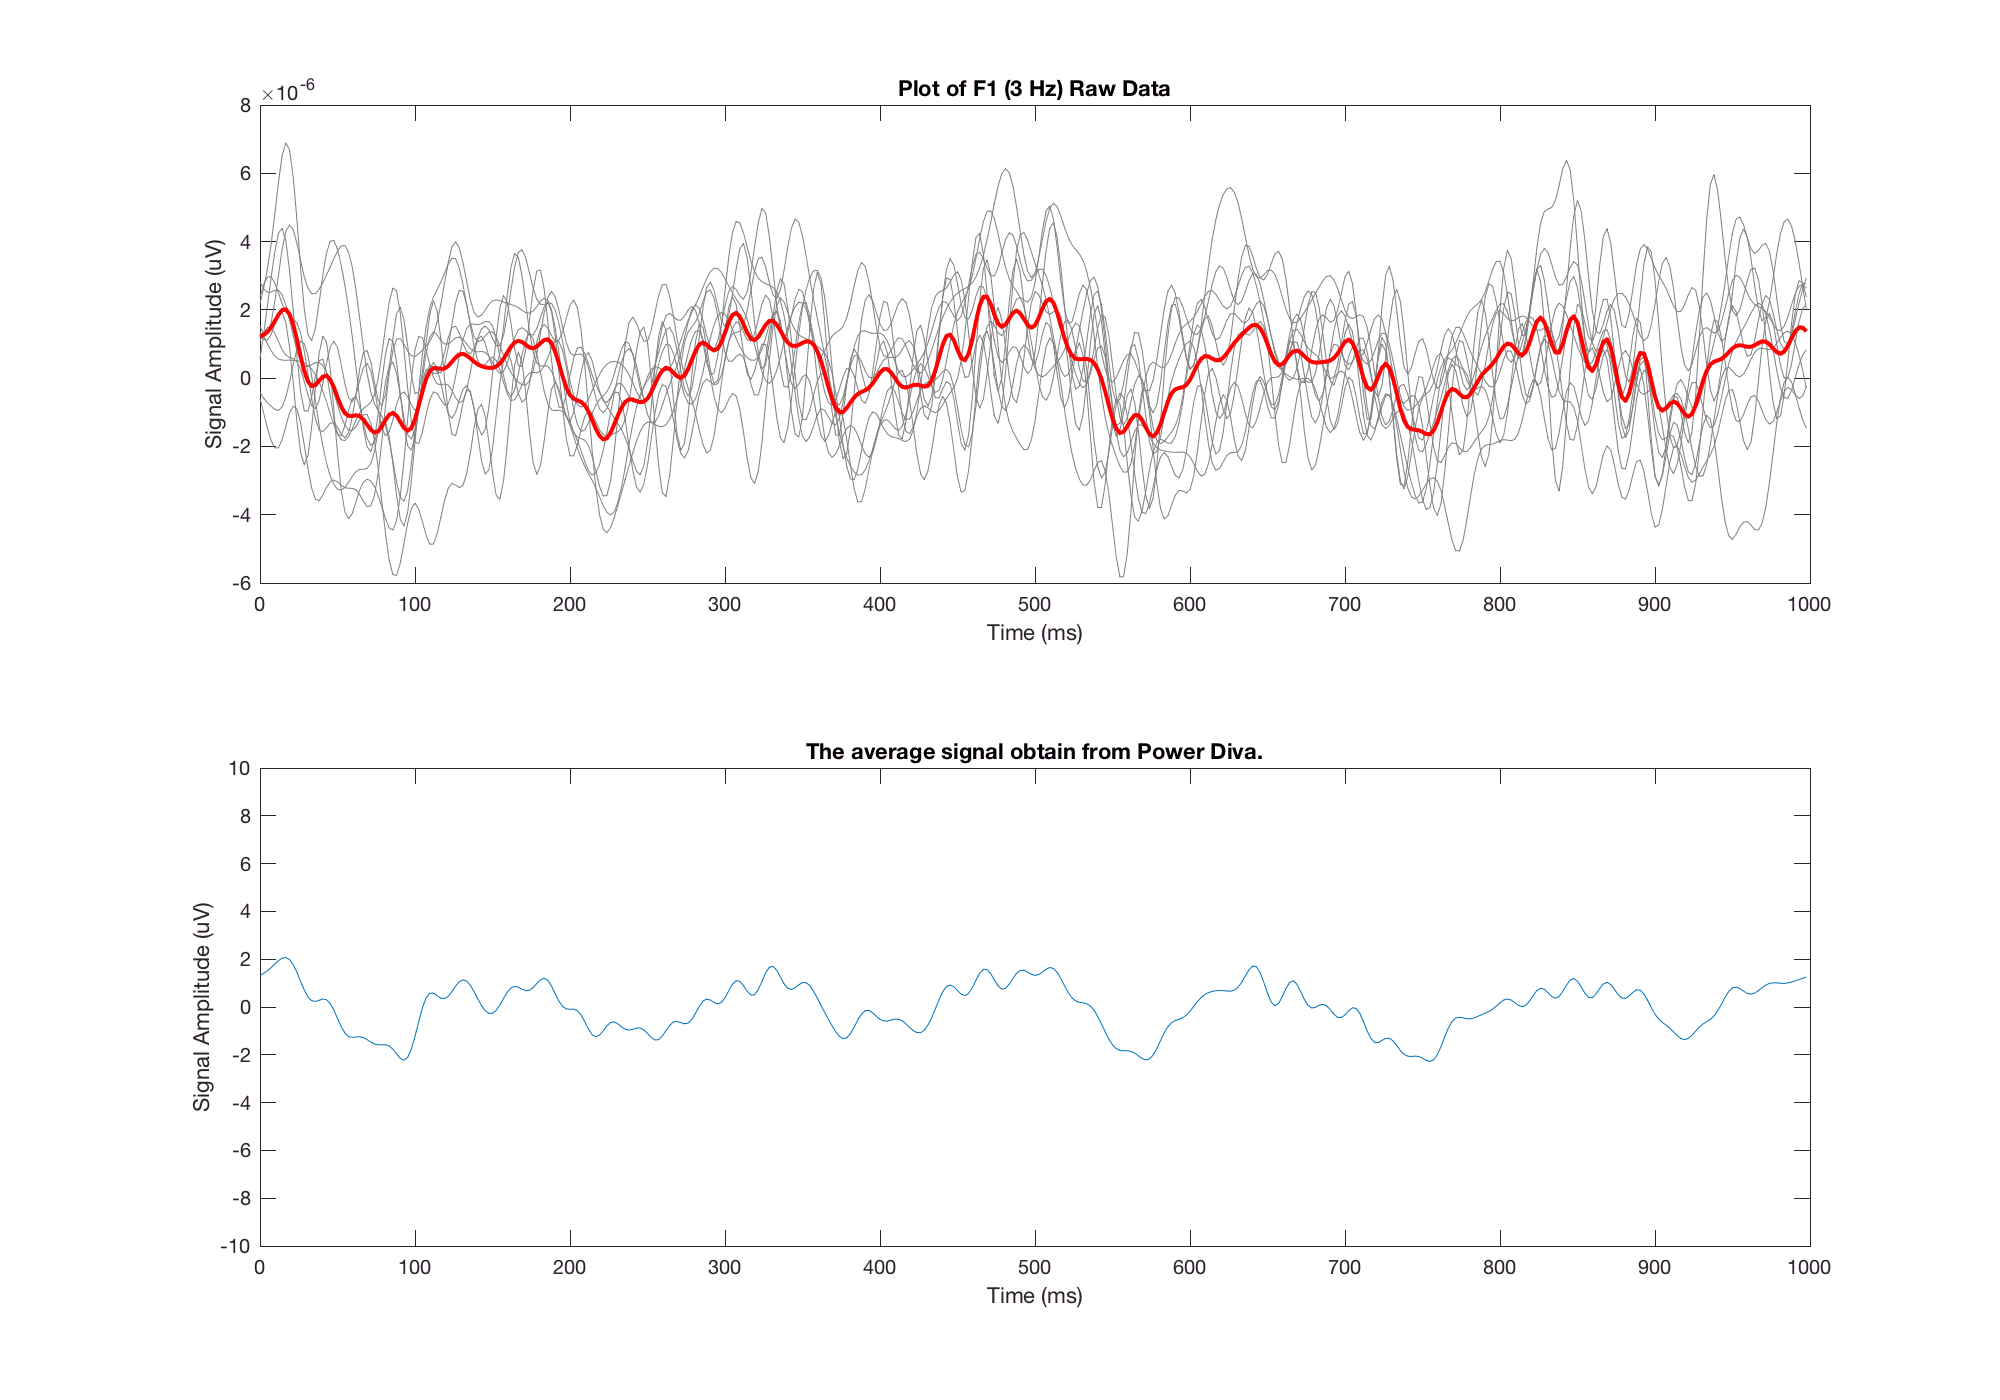

figure(1); 
figure('rend','painters','pos',[10 10 1000 700])
t = 0:1000/420:1000;
t = t(1:420);

subplot(2,1,1)
for i = 1:10
    plot(t, ch75_main(:,i,8), 'color',[.5,.5,.5])
    hold on;
end

plot(t, ch75_2(:,8), 'r', 'LineWidth',2);
title('Plot of F1 (3 Hz) Raw Data')

% plot(t, zeros(1,size(ch75_2(:,8),1)), '-b'); 

xlabel('Time (ms)')
ylabel('Signal Amplitude (uV)')

hold off;

subplot(2,1,2)


processed_data_trial_8 = load('Axx_c008');

plot(t, processed_data_trial_8.Wave(:,75));
title('The average signal obtain from Power Diva.')
xlabel('Time (ms)')
ylabel('Signal Amplitude (uV)')
ylim([-10 10])

Now we plot the data from the second grating. 

figure(2); 
figure('rend','painters','pos',[10 10 1000 700])
subplot(2,1,1)
for i = 1:10
    plot(t, ch75_main(:,i,9), 'color',[.5,.5,.5])
    hold on;
end

plot(t, ch75_2(:,9), 'r', 'LineWidth',2);
title('Plot of F2 (5 Hz) Raw Data')
xlabel('Time (ms)')
ylabel('Signal Amplitude (uV)')

hold off;
subplot(2,1,2)

processed_data_trial_9 = load('Axx_c009');

plot(t, processed_data_trial_9.Wave(:,75));
ylim([-10 10])
title('Processed F2 data from Power Diva')
xlabel('Time (ms)')
ylabel('Signal Amplitude (uV)')


Finding the dominant frequencies in the signals from the 8th and 9th trials. These trials contain each grating (F1 = 3 hz and F2 = 5 hz) separately. 

t = 0:2.3809:1000;
Fs = 420;
x = reshape(ch75_main, [840, 5, 9]);
x = mean(squeeze(x(:,:, 8)),2);

t = 0:1000/420:1000;
t = t(1:420);

x = detrend(x,0);
xdft = fft(x);
freq = 0:Fs/length(x):Fs/2;
xdft = xdft(1:length(x)/2+1);
% plot(freq,abs(xdft));
[~,I] = max(abs(xdft));
fprintf('Maximum frequency in trial 8 (F1 = 3 hz) occurs at %d Hz.\n',freq(I));

Maximum frequency in trial 8 (F1 = 3 hz) occurs at 6 Hz.


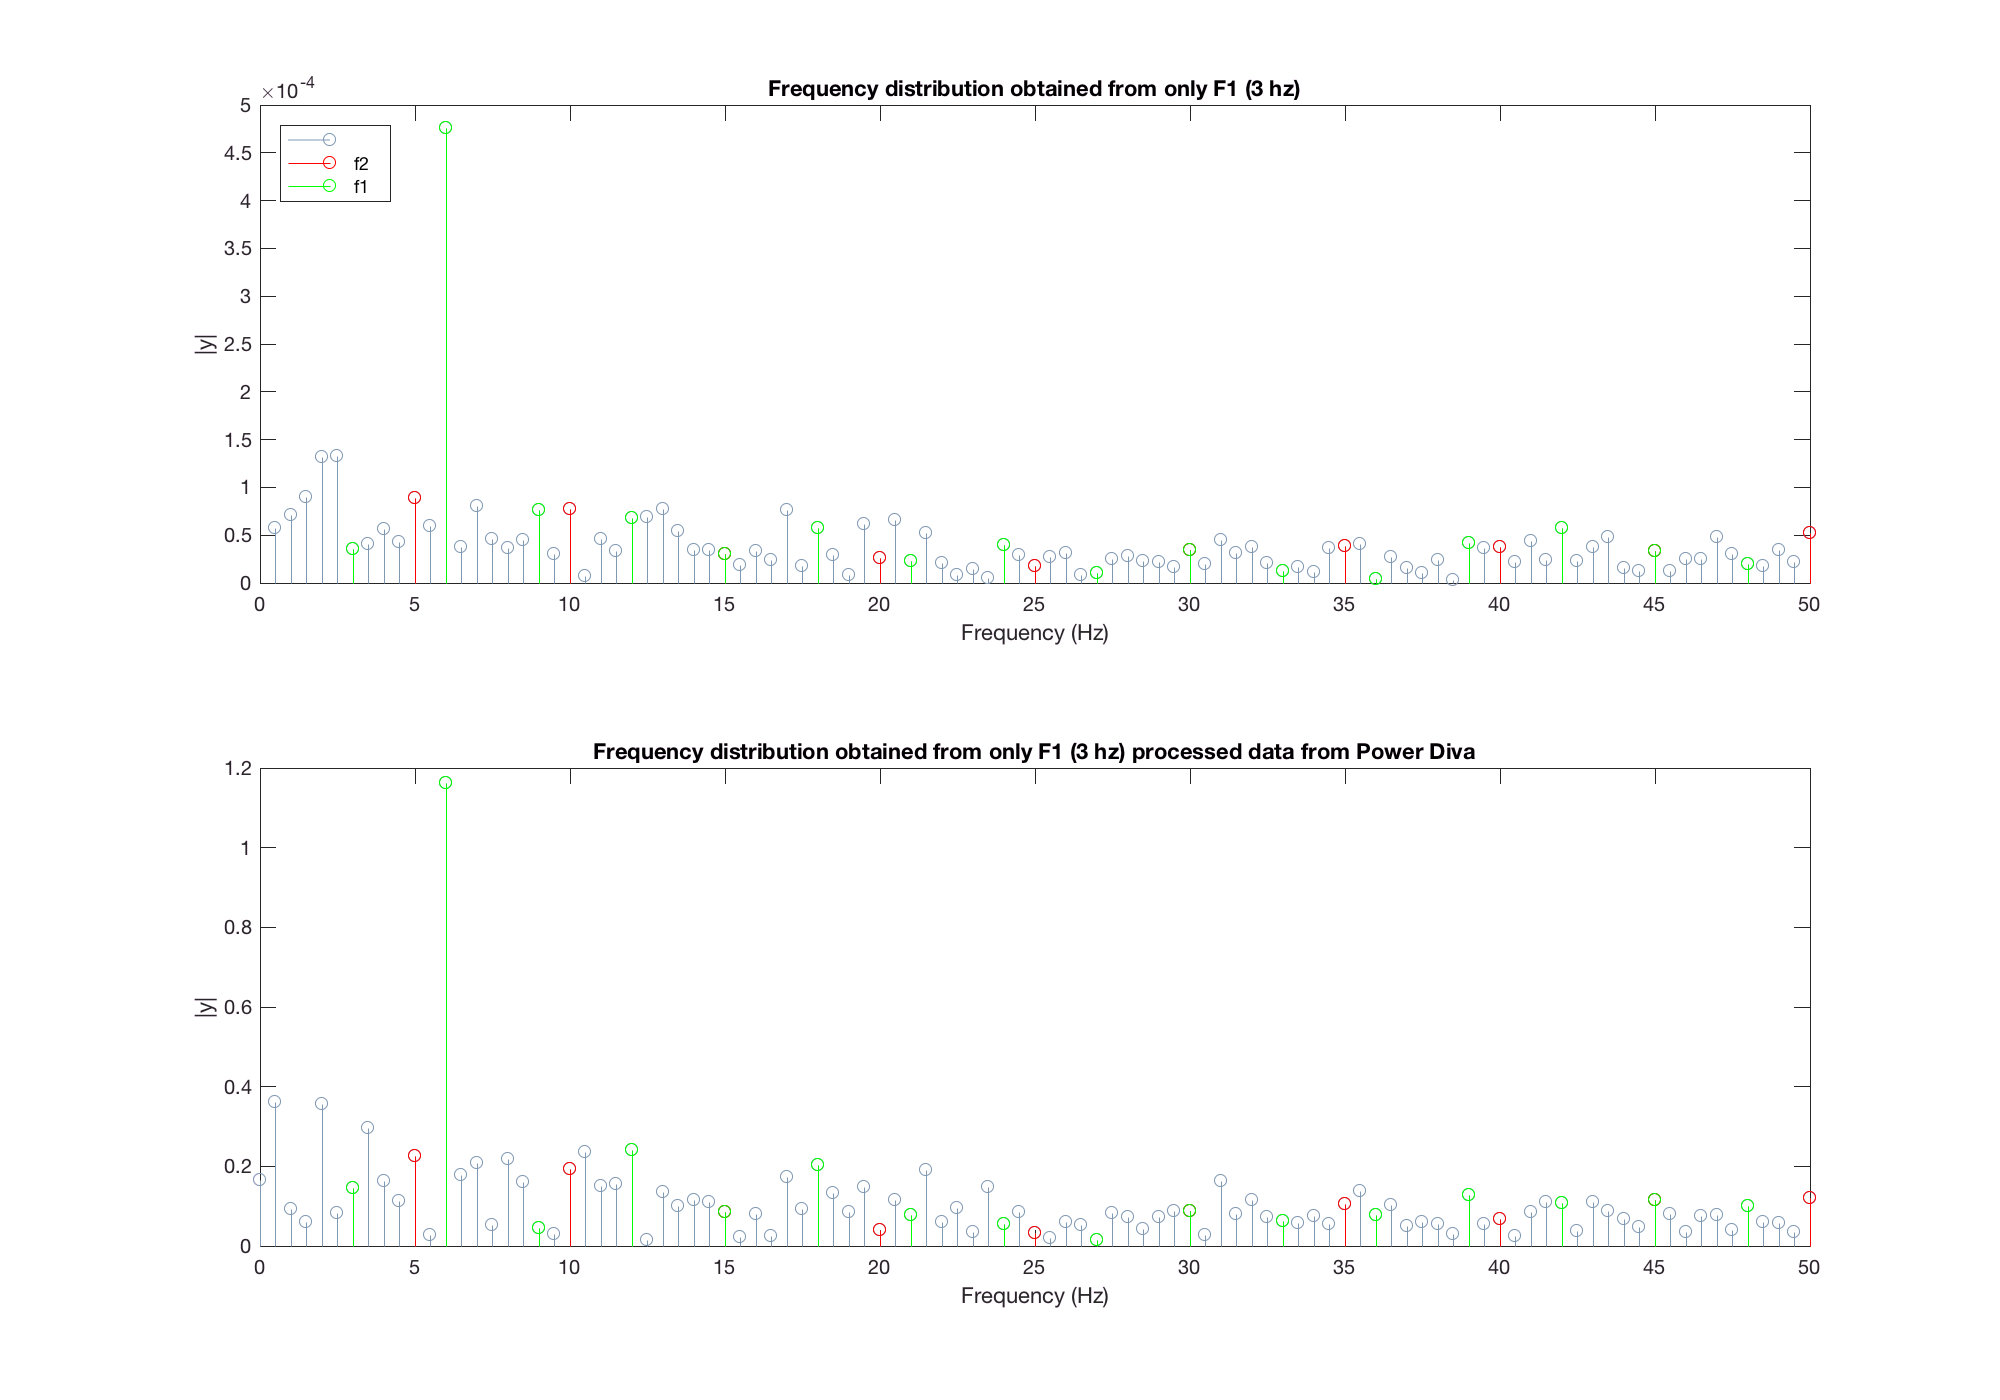

y = fft(x);
figure(3);
ly = length(y);
f = (-ly/2:ly/2-1)/ly*Fs;
a = abs(fftshift(y));

x1= f(f>0); % this is used for plotting the frequency values. 
y1 = a(f>0); % excluding the negative frequency values

first_grating_frequency_idx = [6:6:100]; % these indices are used for graphing them in different colors
second_grating_frequency_idx = [10:10:100];

subplot(2,1,1)

stem(x1(1:100),y1(1:100), 'color',[.5,.6,0.7]); % plotting all frequencies in gray 
hold on;

stem(x1(second_grating_frequency_idx),y1(second_grating_frequency_idx), 'r'); % plotting f2 harmonics in red

stem(x1(first_grating_frequency_idx),y1(first_grating_frequency_idx), 'g'); %plotting f1 harmonics in green

legend( {'', 'f2','f1'}, 'Location', 'NorthWest' )

xlabel 'Frequency (Hz)'
ylabel '|y|'
title('Frequency distribution obtained from only F1 (3 hz)')

hold off;

subplot(2,1,2)
k = [0:0.5:100/2];
stem(k,processed_data_trial_8.Amp(1:101,75), 'color', [.5,.6,0.7 ]) % I'm choosing 1:101 because I want to see the frequency up to 50 Hz
% the power diva program does fft in a different way, so each point is 0.5 hz apart from the other one. for this reason, 1:101 means
% 0.0 hz to 50 hz 

hold on;

stem(k([11:10:101]),processed_data_trial_8.Amp([11:10:101],75), 'r'); % plotting f2 harmonics in red
% it starts from 11 because the index in power diva is zero based, so in matlab I added one to it. 

stem(k([7:6:101]),processed_data_trial_8.Amp([7:6:101],75), 'g'); %plotting f1 harmonics in green

xlabel 'Frequency (Hz)'
ylabel '|y|'
title('Frequency distribution obtained from only F1 (3 hz) processed data from Power Diva')

hold off;



x = reshape(ch75_main, [840, 5, 9]);
x = mean(squeeze(x(:,:, 9)),2);

x = detrend(x,0);
xdft = fft(x);
freq = 0:Fs/length(x):Fs/2;
xdft = xdft(1:length(x)/2+1);
% plot(freq,abs(xdft));
[~,I] = max(abs(xdft));
fprintf('Maximum frequency in trial 9 (F1 = 5 hz) occurs at %d Hz.\n',freq(I));

Maximum frequency in trial 9 (F1 = 5 hz) occurs at 10 Hz.


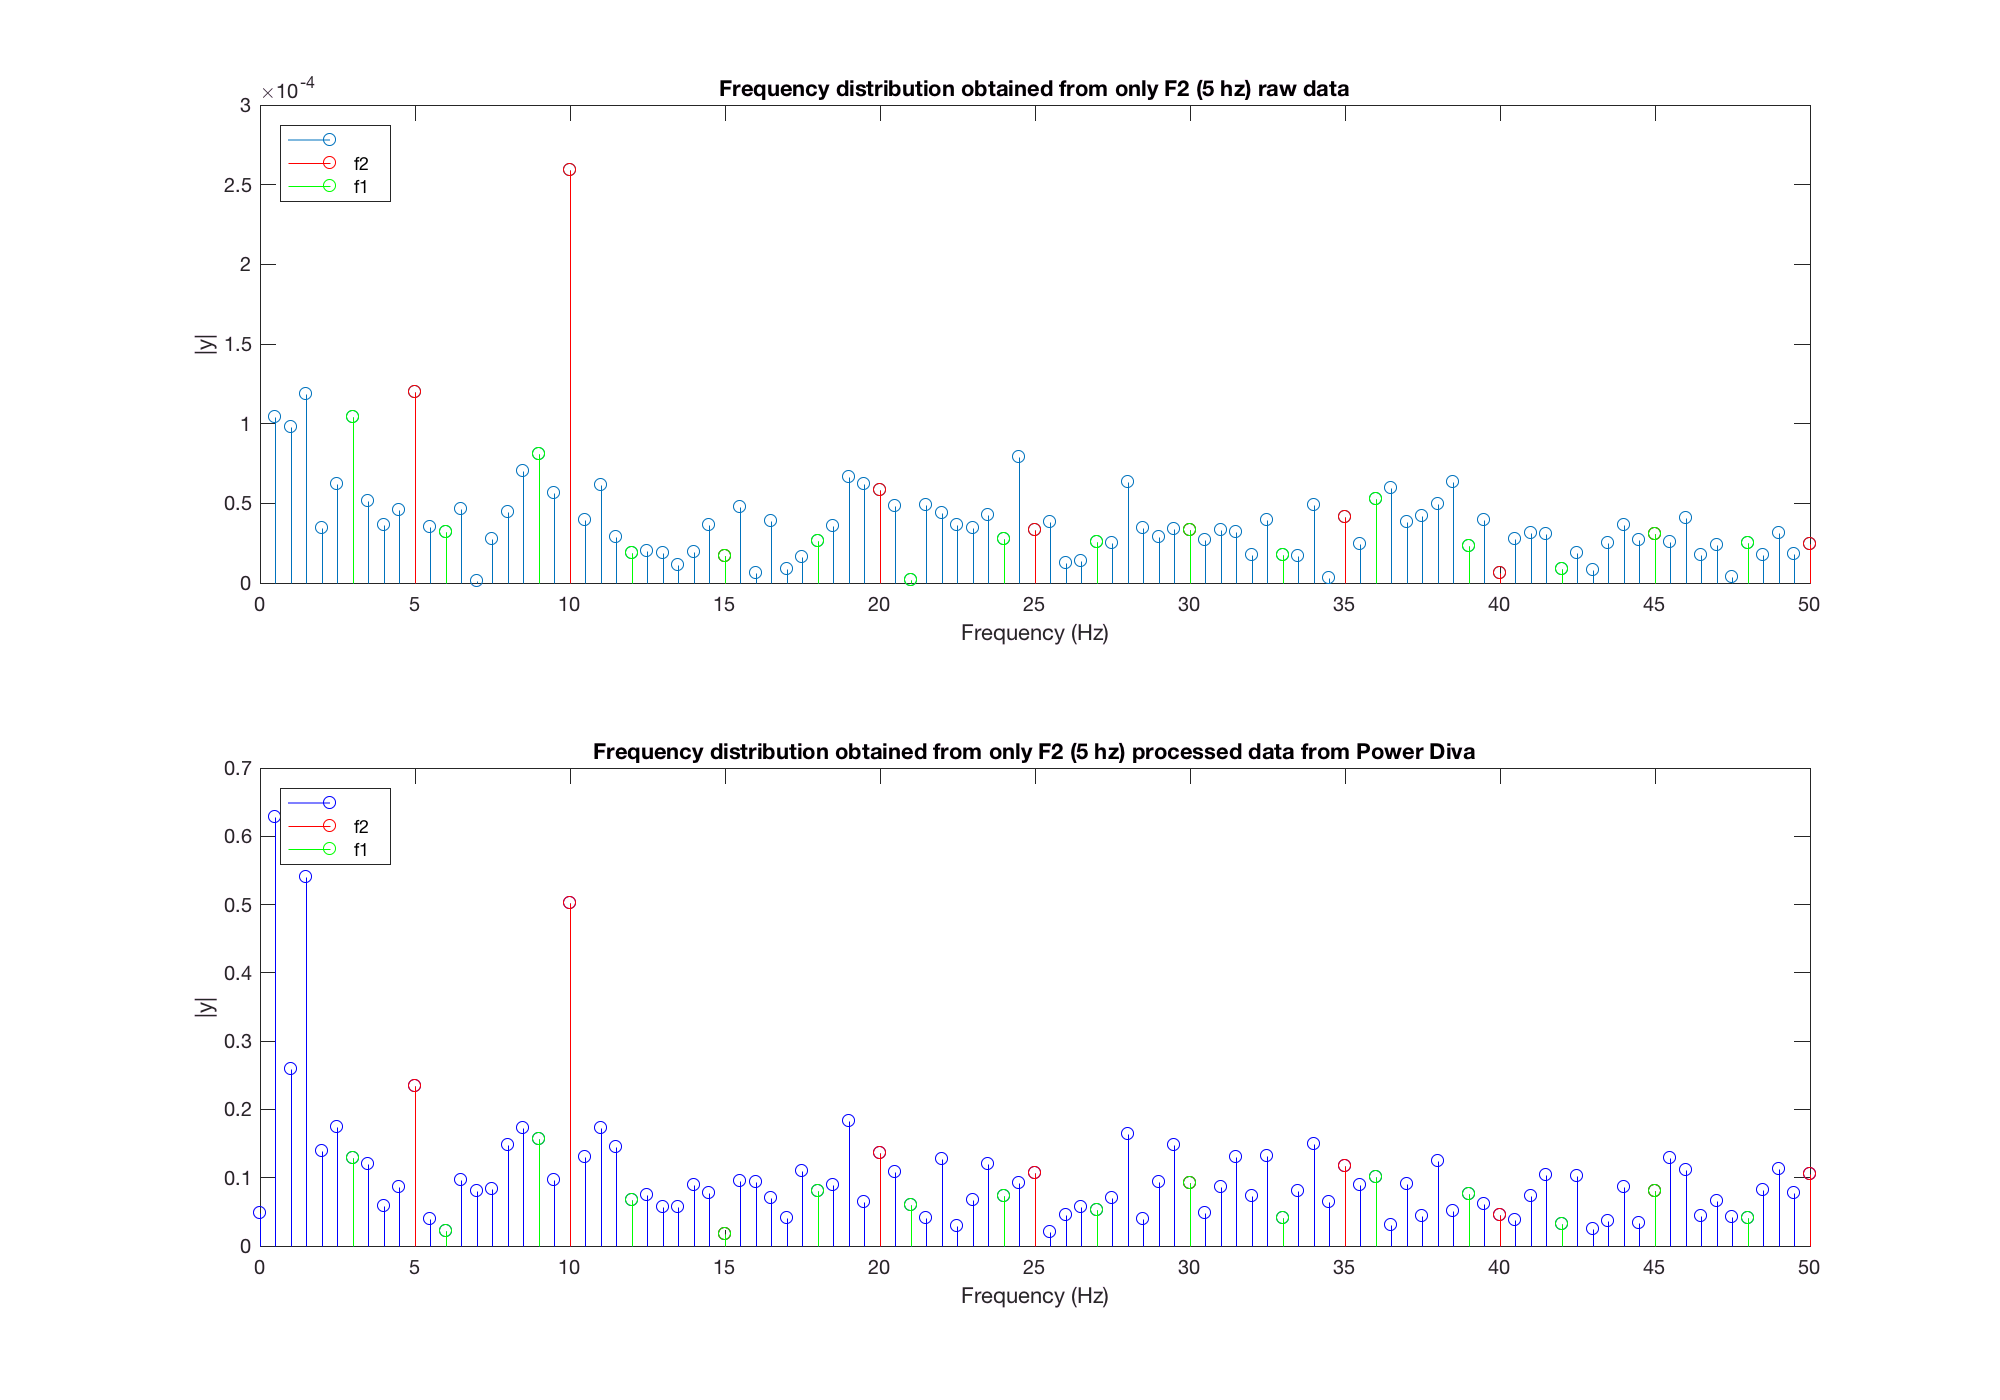


y = fft(x);
figure(4);
figure('rend','painters','pos',[10 10 1000 700])
subplot(2,1,1)
ly = length(y);
f = (-ly/2:ly/2-1)/ly*Fs;
a = abs(fftshift(y));
x1= f(f>0); % this is used for plotting the frequency values. 
y1 = a(f>0); % excluding the negative frequency values

first_grating_frequency_idx = [6:6:100]; % these indices are used for graphing them in different colors
second_grating_frequency_idx = [10:10:100];

stem(x1(1:100),y1(1:100));
hold on;
stem(x1(second_grating_frequency_idx),y1(second_grating_frequency_idx), 'r');

stem(x1(first_grating_frequency_idx),y1(first_grating_frequency_idx), 'g');

xlabel 'Frequency (Hz)'
ylabel '|y|'
legend( {'', 'f2','f1'}, 'Location', 'NorthWest' )
title('Frequency distribution obtained from only F2 (5 hz) raw data')
hold off;
subplot(2,1,2) % plotting the data exported from power diva

k = [0:0.5:100/2];
stem(k,processed_data_trial_9.Amp(1:101,75), 'b'); % I'm choosing 1:101 because I want to see the frequency up to 50 Hz
% the power diva program does fft in a different way, so each point is 0.5 hz apart from the other one. for this reason, 1:101 means
% 0.0 hz to 50 hz 

hold on;

stem(k([11:10:101]),processed_data_trial_9.Amp([11:10:101],75), 'r'); % plotting f2 harmonics in red

stem(k([7:6:101]),processed_data_trial_9.Amp([7:6:101],75), 'g'); %plotting f1 harmonics in green
xlabel 'Frequency (Hz)'
ylabel '|y|'
title('Frequency distribution obtained from only F2 (5 hz) processed data from Power Diva')
legend( {'', 'f2','f1'}, 'Location', 'NorthWest' )

hold off;

Now We're going to look into the phase of the signals. At their particular frequencies (3 and 5 hz).

% work in progress 

Plotting the data for the rest of the trials. As you can see, the intermodulatory frequencies (2 hz and 8 hz) are highest in the first trials where the gratings are overlapping the most. As the angle between them increase, their intermodulations decrease, and we begin seeing more fundamental and harmonic frequencies. 

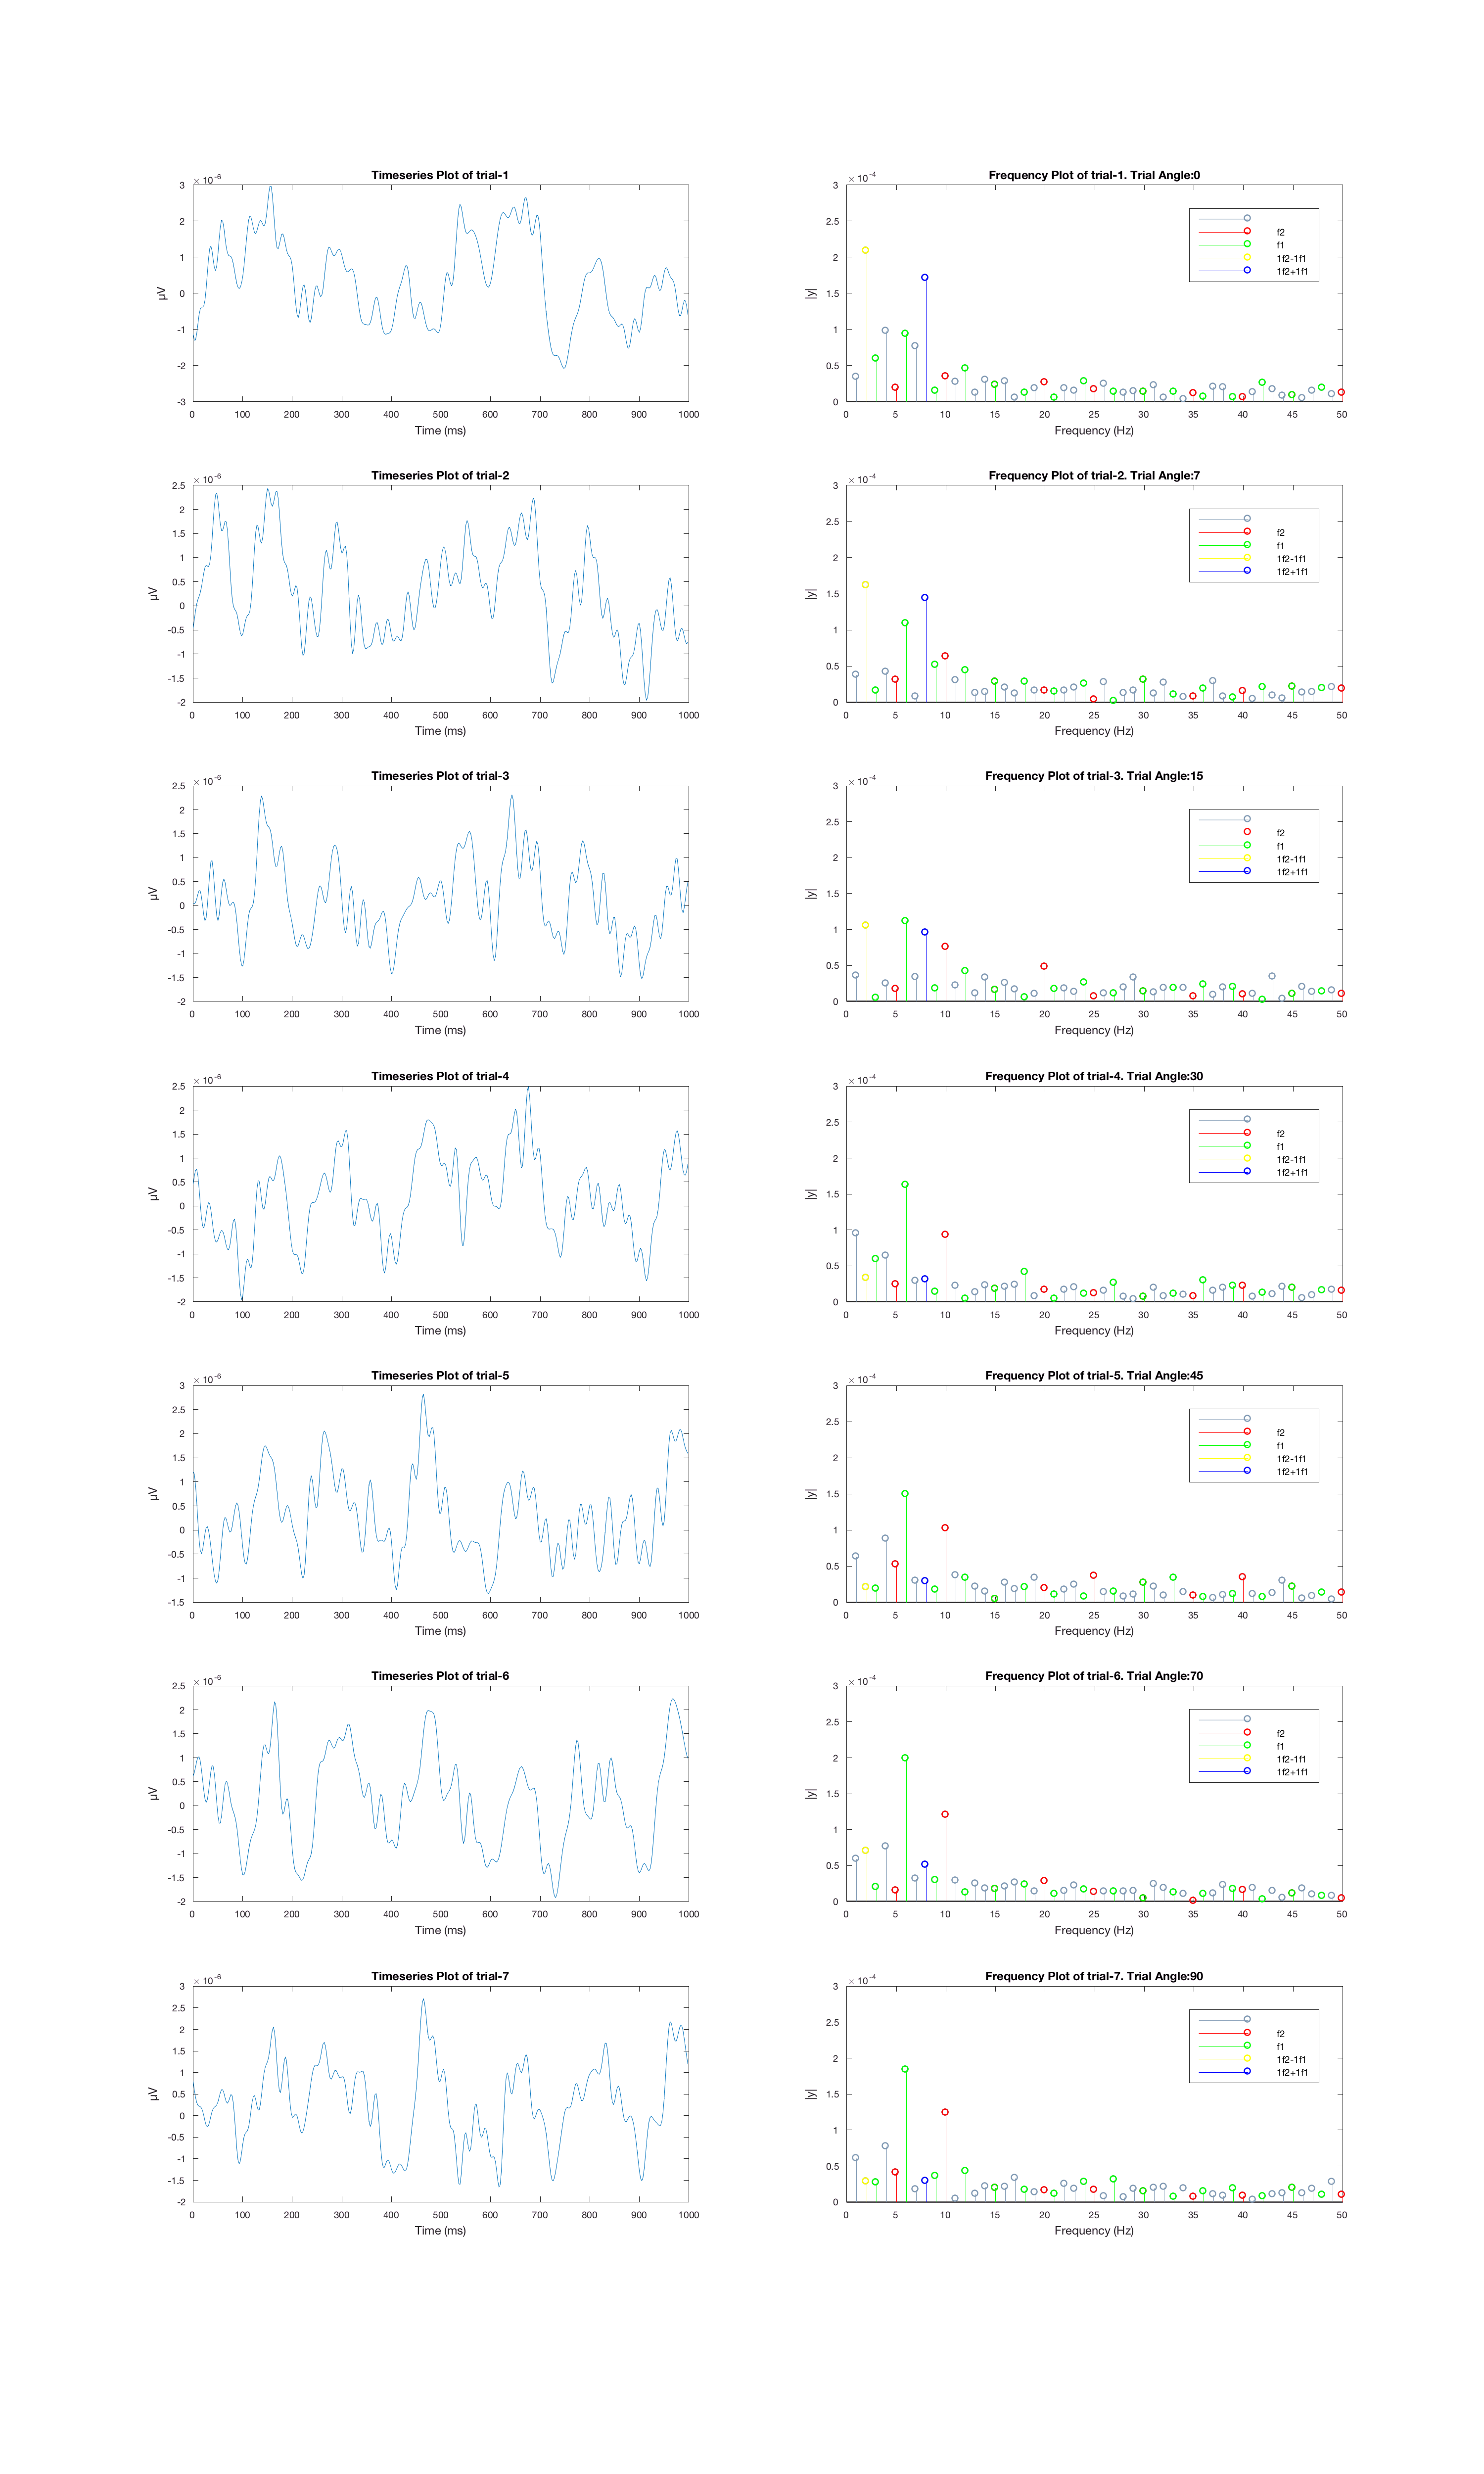

figure(5);
trial_angles = [0,7, 15, 30, 45, 70, 90];
figure('rend','painters','pos',[10 20 1500 2500])
t = 0:1000/420:1000;
t = t(1:420);
j = 1;
d = 1;
for i = 1:7*2
    subplot(7,2,i)
    if mod(i,2) ~= 0
        plot (t, ch75_2(:,j))
         title(strcat('Timeseries Plot of trial- ', num2str(j)))
        xlabel('Time (ms)')
        ylabel ('µV')

        j = j+1;
    else
        z(d,:) = freq_plot(ch75_2(:,d),420, 50);
        title(strcat('Frequency Plot of trial- ', num2str(d),'. Trial Angle:', num2str(trial_angles(d))));
        ylim([0, 3 *10^-4]);
         d = d+1;
    end
end

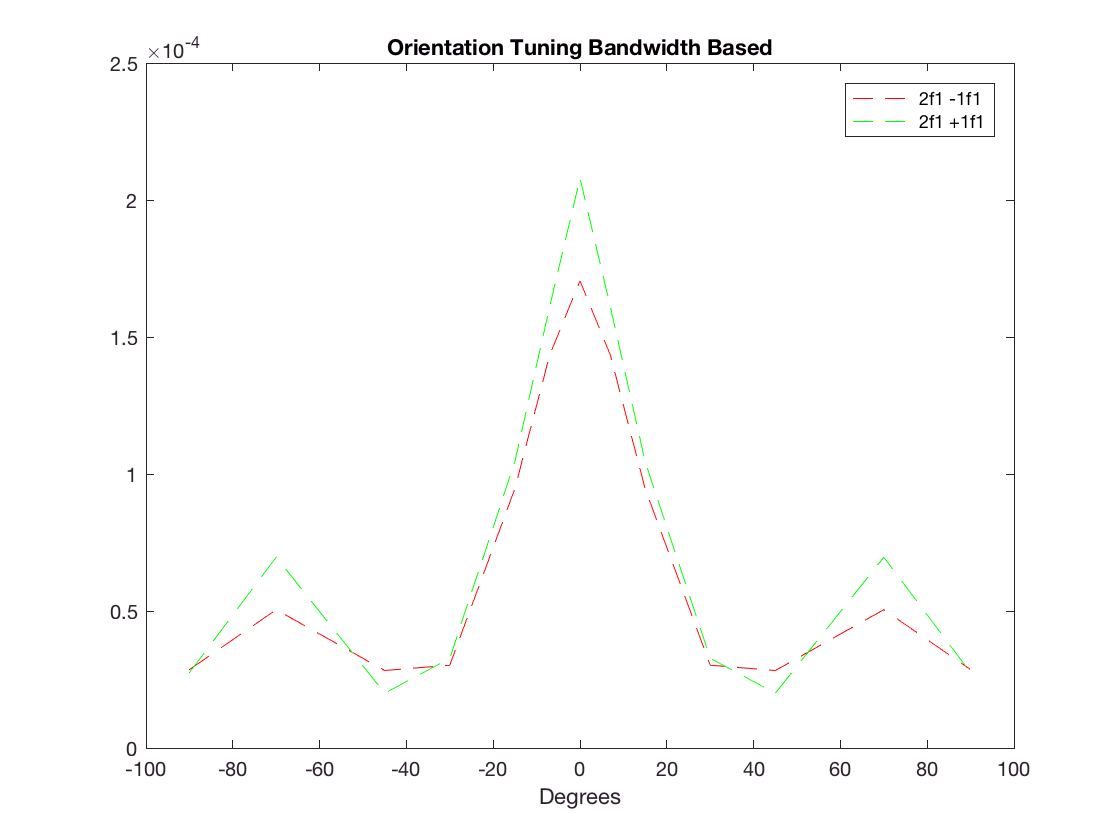

figure(10);
% plotting orientation tuning bandwidth based on 2f2 amplitude 
% we got z value through the loop above. It contains the amplitude of 2f2 for each trial. We then mirror it in here to make the gaussian distribution. 
z2 = vertcat(flip(z(2:end,2),1),z(:,2)); %1f2 - 1f1
z3 = vertcat(flip(z(2:end,1),1),z(:,1)); %1f2 + 1f1

angles = [-90 ,-70, -45, -30, -15 ,-7,0, 7, 15, 30, 45, 70, 90];
% plot([0, 7, 15, 30, 45, 70, 90],z(:,1))
plot(angles, z2, '--r');
hold on;
plot (angles, z3, '--g');
% plot([0, 7, 15, 30, 45, 70, 90],z(:,2))
title( 'Orientation Tuning Bandwidth Based');
xlabel('Degrees')
legend ('2f1 -1f1', '2f1 +1f1', 'Location','NorthEast')

Now let's see what happens if we add and subtract the values of F1 and F2 trial signals. Will we get something similar to any graph above?

figure(7);
figure('rend','painters','pos',[10 10 1000 700])


subplot(6,2,1)
plot(t, ch75_2(:,8))
title('plot of trial 8 (3 hz)')
xlabel('Time (ms)')
ylabel ('µV')

subplot(6,2,2)
x = reshape(ch75_main, [840, 5, 9]);
x = mean(squeeze(x(:,:, 8)),2);
freq_plot(x, 420, 100)

ans =    1.0e-03 *

    0.1317
    0.0360


ylim([0,6 *10^-4])
title('freq plot of trial 8 (3 hz)')

subplot(6,2,3)
plot(t, ch75_2(:,9))
title('plot of trial 9 (5 hz)')
xlabel('Time (ms)')
ylabel ('µV')


subplot(6,2,4)
x = reshape(ch75_main, [840, 5, 9]);
x = mean(squeeze(x(:,:, 9)),2);
freq_plot(x, 420, 100)

ans =    1.0e-04 *

    0.3392
    0.4399


title('freq plot of trial 9 (5 hz)')

subtract_fundamentals = (ch75_2(:,9) - ch75_2(:,8));
add_fundamentals = (ch75_2(:,9) + ch75_2(:,8));
ylim([0,6 *10^-4])
% subplot(4,2,5)
% plot(t, subtract_fundamentals);
% title( 'Subtracting time series data (t9 - t8)')
% xlabel('Time (ms)')
% ylabel ('µV')
% 
% 
% subplot(4,2,6)
% % a = ch75_main, [840, 5, 9];
% x = reshape(ch75_main, [840, 5, 9]);
% x = mean(squeeze(x(:,:, 9)),2) - mean(squeeze(x(:,:, 8)),2);
% 
% freq_plot(x, 420, 100)

subplot(6,2,5)

plot(t, add_fundamentals);
title( 'Adding time series data of t9 + t8')
xlabel('Time (ms)')
ylabel ('µV')


subplot(6,2,6)

x = reshape(ch75_main, [840, 5, 9]);
x = mean(squeeze(x(:,:, 9)),2) + mean(squeeze(x(:,:, 8)),2);

freq_plot(x, 420, 100)

ans =    1.0e-03 *

    0.1095
    0.0697


ylim([0,6 *10^-4])
subplot(6, 2, 7); 

plot(t,ch75_2(:,7))

title('Plot of trial 7 (90 degrees difference)')

subplot(6, 2, 8); 

freq_plot(ch75_2(:,7), 420, 50);
ylim([0,6 *10^-4])
subplot(6,2,9)

plot(t,ch75_2(:,7) - add_fundamentals)
title('plot of subtracting trial 7 data from (t9 + t8)')

subplot(6,2,10)

freq_plot(ch75_2(:,7) - add_fundamentals, 420, 50);
ylim([0,6 *10^-4])

subplot(6,2,11)
plot(t,ch75_2(:,1))
title('trial 1')
subplot(6,2,12)
freq_plot(ch75_2(:,1), 420, 50)

ans =    1.0e-03 *

    0.2079
    0.1705


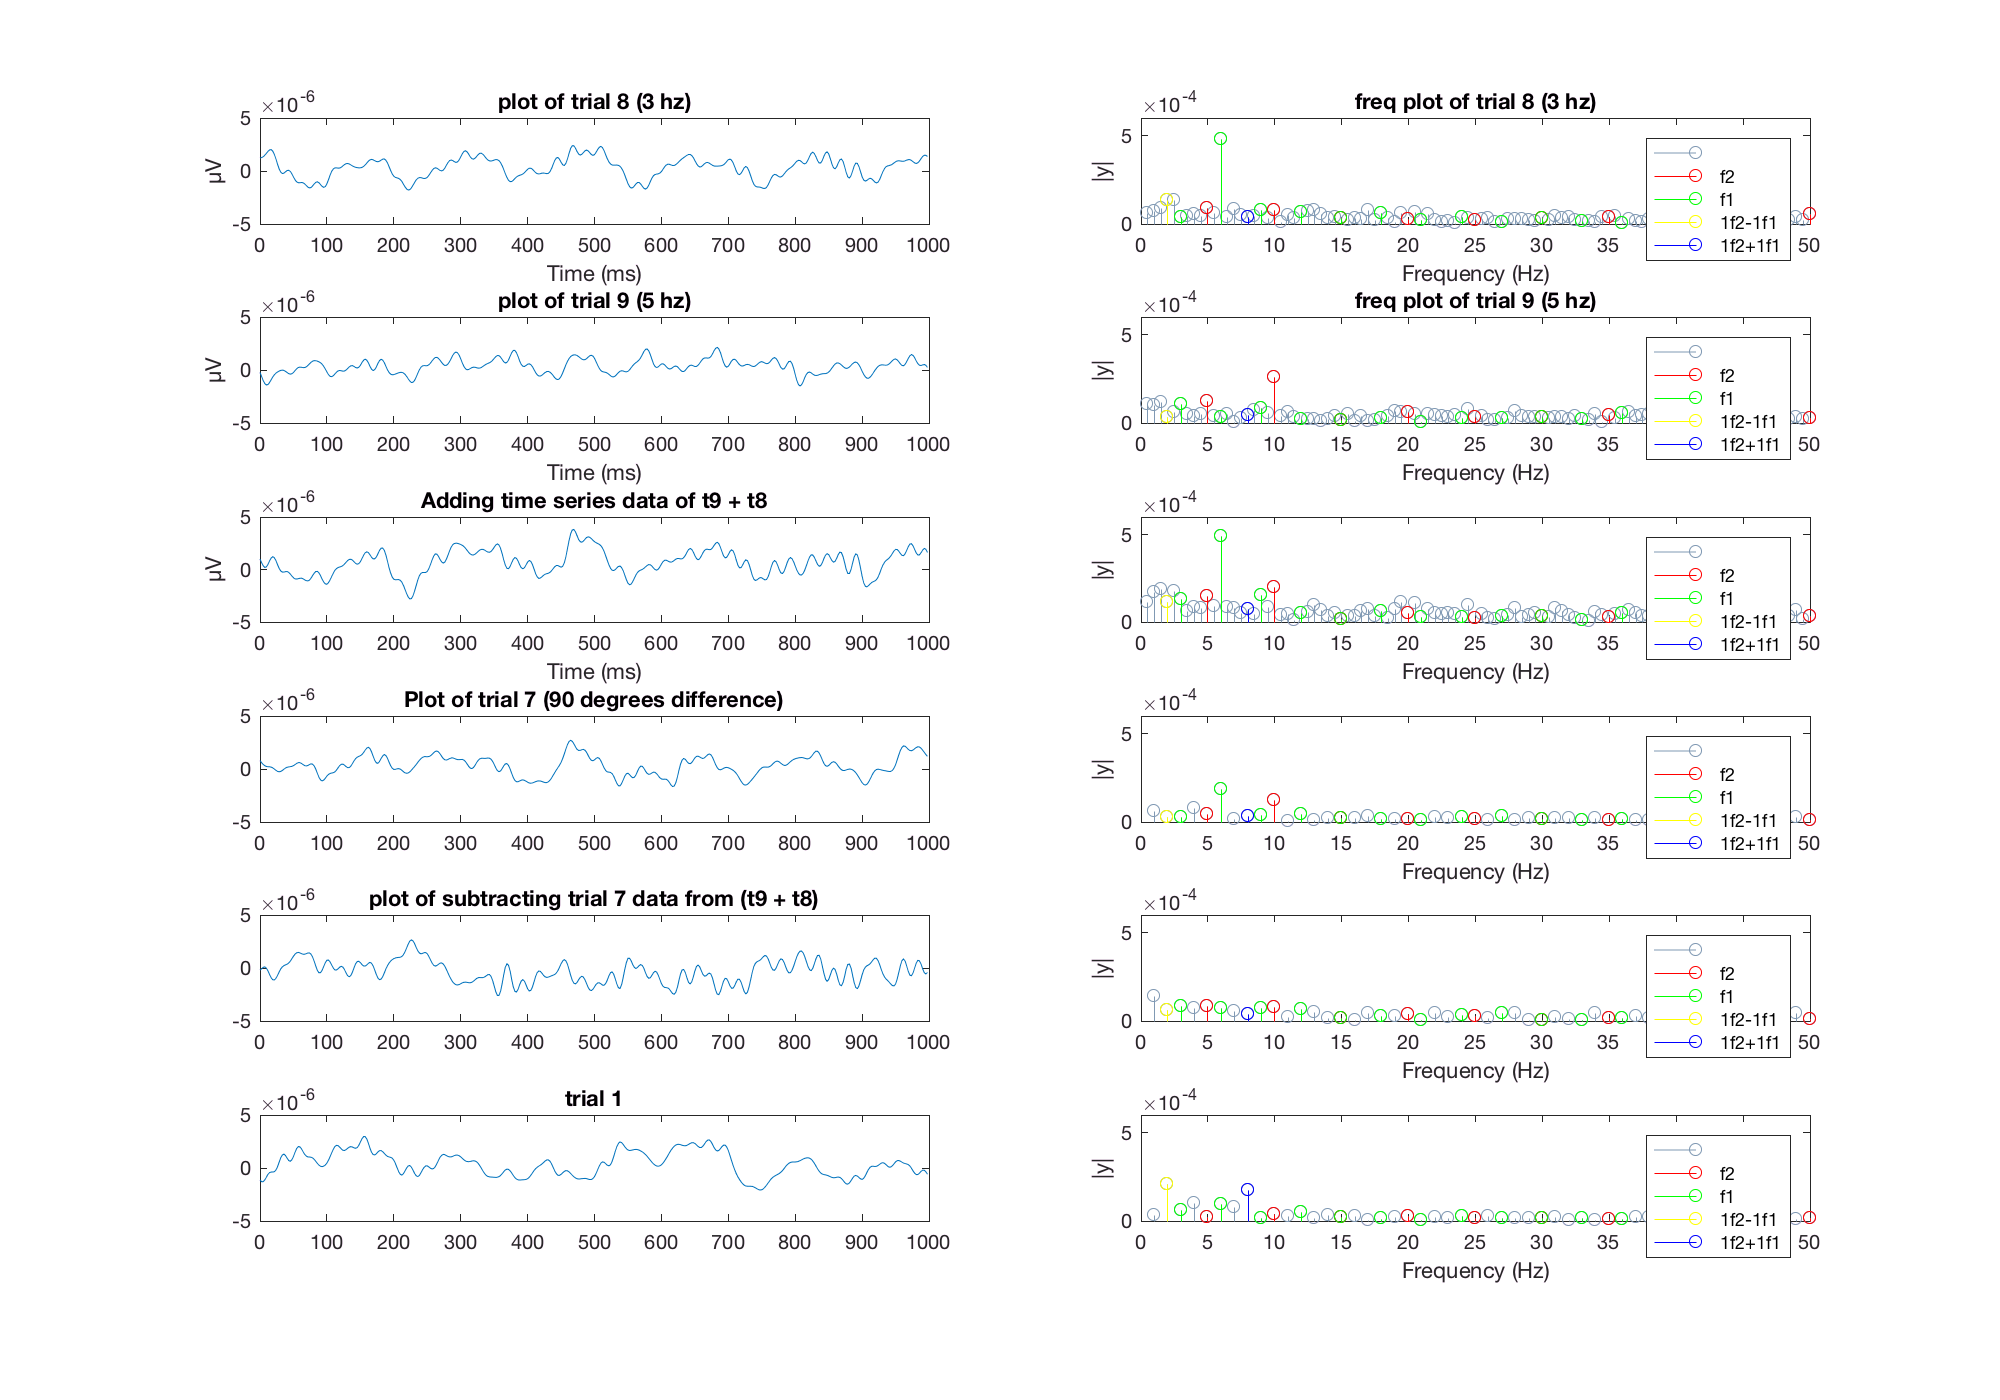

ylim([0,6 *10^-4])


% figure(7);





Now let's plot the frequency graph of trial one, where the angle different between the gratings is zero. 